# Homework 5

## Due Wednesday, May 6 before 5:00pm

*For Part 1, submit your handwritten work using Gradescope. For Parts 2-4, use [Live Editor > Save > Export to PDF] to prepare your submission for Gradescope.*

## Part 1: Deriving an estimator for $y=\beta_1 x$

In class we derive least-squares estimators for the linear models $y=\beta_0$ and $y=\beta_0+\beta_1x$. For this exercise you will derive a formula to fit a single parameter model $y=\beta_1x$ to a set of $n$ datapoints.

**a.)** Begin with the sum of squared error $\sum_{i=1}^n(y^\mathrm{obs} - y^{pred})^2$. Write this expression after substituting the linear model for $y^\mathrm{pred}$.

**b.)** Our goal is to minimize the sum squared error, which can be found when the partial derivative of the sum squared error with respect to the parameter $\beta_1$ is zero. Find and expression for $\beta_1$.

**c.)** Using your formula for $\beta_1$, fit the model $y=\beta_1x$ to the five data points in the table on page 1 of Chapter 14. Compare your value of $\beta_1$ to the value found when fitting the data to the model $y=\beta_0+\beta_1x$ in section 14.2.

**d.)** We want to be sure that we're minimizing, not maximizing the sum squared error. Using a second derivative test, show that your estimate for $\beta_1$ is a minimum. Be sure to explain your reasoning.

**Parts 2-4 use data from the MAT file HW5_data**`.mat`**. **Download this file and run

load HW5_data.mat

to load variables `x`, `y`, `blood`, and `ecm` into the workspace.

## Part 2: Polynomial Fitting

Variables `x` and `y` contain 12 values from an unknown cubic polynomial, i.e.


$$y = \beta_0+\beta_1x+\beta_2x^2+\beta_3x^3$$


Using the values `x` and `y`, compute estimates for parameters $\beta_0, \ldots, \beta_3$ using linear regression. **For this problem, you are not allowed to use **`fitlm`**, **`regress`**, **`polyfit`**, or any other linear regression or curve fitting tools.** You must construct the design matrix and calculate parameter estimates via pseudoinversion.

% place your code here

Using your parameter estimates, plot the points in variables `x` and `y` and a line corresponding to the best fit polynomial. Both the points and the line should be on the same plot.

% place your code here

## Part 3: Blood Metabolite Diagnostic for Fungal Infections 

You are tasked with diagnosing a bloodborne fungal infection. Ideally, you would measure the number of colony forming units (CFUs) per ml of blood. However, the fungus is slow growing outside the body, so accurate CFU counts take weeks. Instead, you hope to use standard measurements from a blood metabolic panel to predict the CFUs/ml in a sample.

The Matlab table blood contains data from a 250-patient clinical trial. Each datapoint has values for all 14 standard blood metabolite readings:

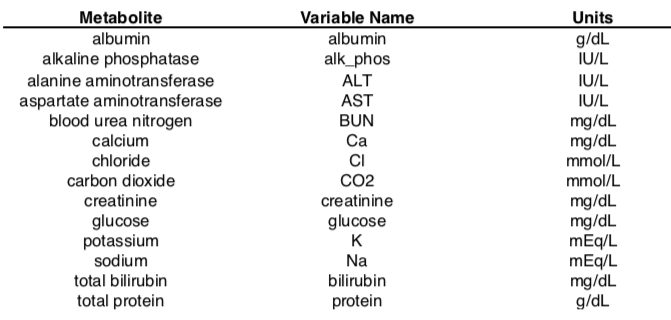

The blood table also contains the log(CFU) counts for each sample. (*Note that we use log(CFU) since CFU counts vary exponentially. This is unrelated to the logit function or logistic regression.*)

**a.)** Using linear regression, build a model that predicts log(CFU) counts with blood metabolite readings. 

% place your code here

Which metabolite readings are significantly predictive of the CFU counts? Do these metabolite levels correlate positively or negatively with fungus levels? By how much?

*<place your answer here>*

**b.)** During sepsis, the number of fungal cells in the blood increases by 100 fold. Would your model be able to predict this level of change using metabolites? Why or why not?

*<place your answer here>*

## Part 4: Cell/Matrix Interactions

Multivariable linear regression can be used to analyze large-scale datasets and to develop models that describe complex biological phenomena. The dataset that you will analyze in this problem is from an experiment designed to study how cancer cells interact with a set of proteins termed extracellular matrix (ECM) proteins.

ECM proteins (collagen is a very common example) provide structure to normal tissues as well as diseased tissues such as tumors. In addition to a structural role, ECM proteins can also provide important signals to cancer cells, which can help the cancer cells survive, proliferate, or migrate to other sites in the body. Although it is clear that ECM proteins are important in cancer, the overall matrix of a tumor consists of a complex combination of many different ECM proteins.  What is not currently known is, (i) what are the most important ECM proteins in different types of cancer, and (ii) what happens when cancer cells interact with combinations of ECM proteins at the same time?

For this problem, you will analyze actual data associated with the following experiment.  

- A lung cancer cell line was cultured on 55 different combinations of 10 ECM proteins (10 proteins listed in next bullet). These unique combinations included the 10 ECM proteins individually, and the 45 2-factor combinations of the 10 proteins. For example, one of the conditions was collagen 1 (C1) by itself, and then 9 other conditions were C1 paired with each of the other ECM proteins.

- ECM proteins (and abbreviations):  C1= collagen 1; C3= collagen 3; C4= collagen 4; G3= galectin-3; G8= galectin-8; OP= osteopontin; TC= tenascin-C; TR= tenascin-R; FN= fibronectin; LN= laminin

- After culture, the number of adherent cancer cells was quantified. If an ECM combination enhanced the number of adherent cells, then this ECM likely promotes cancer cell adhesion, survival, and possibly proliferation.

- For each ECM combination, there were approximately 15-20 replicate measurements of adherent cell number.

From this dataset, the goal is to quantitatively determine how individual ECM proteins, and specific combinations of ECM proteins, control lung cancer cell adhesion (adherent cell number).

**a.)** Fit a linear model to predict the number of adherent cells for each ECM and their interactions. The data are stored in the variable `ecm`.

Notes (see `help fitlm` for more details):

- This experiment examined 10 distinct ECMs, not 10 variations on one “standard” ECM. As such, there should be no intercept in your model. You can disable the intercept with the ‘intercept’ argument.

- You can easily include interactions for all variables using the ‘interactions’ argument to fitlm.

- You can specify the response variable with the ‘ResponseVar’ argument.

- The ECM values are categorical. You can tell fitlm these are categorical variables using the ‘CategoricalVars’ option.

- Large datasets are subject to false positives. Use a correction (like the Bonferroni correction) to your significance level when interpreting *p*-values.

% place your code here

**b.)** What ECMs have a significant coefficient for the linear term? What does this coefficient mean? If any linear terms (called “main effects”) do not have a significant coefficient, what does this mean?

*<place your answer here>*

**c.)** Which ECMs interact significantly? Which pair has the strongest interaction for promoting adherence? Which pair has the strongest inhibition of adherence?

*<place your answer here>*

**d.)** Compare the root mean squared error of your model with the average effect size. Are you able to accurately predict adherence based on the ECM? If not, are the coefficients still meaningful, why or why not? 

*<place your answer here>*